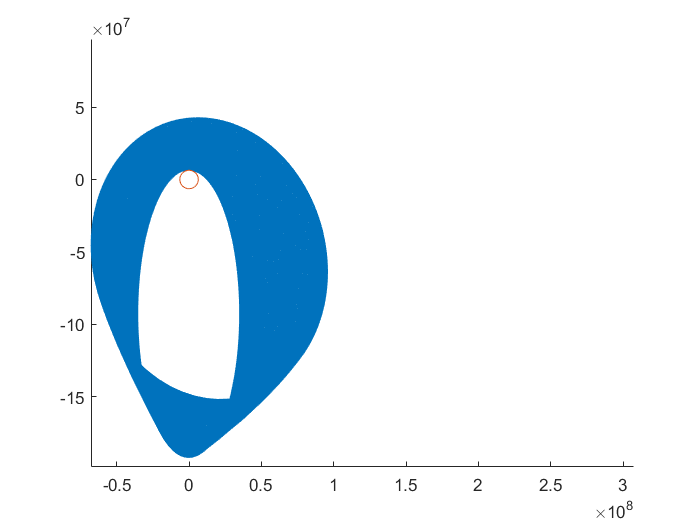

earthVelocity = [11000,0]; % (m/s)

[T, M] = body_2D_ode45(earthVelocity);

clf;
hold on
plot(M(:,1), M(:,2));

% Plot Earth
points = linspace(0, 2*pi, 500);
r = 6.371e6;
x = r*cos(points);
y = r*sin(points);
plot(x,y)


% Plot Moon
points = linspace(0, 2*pi, 500);
r = 1.738e6;
x = r*cos(points) + 3.844e8;
y = r*sin(points);
plot(x,y)

axis equal